clear

a = arduino('COM11','Uno','Libraries','Servo');

s = servo(a, 'D3', 'MinPulseDuration', 700*10^-6, 'MaxPulseDuration', 2300*10^-6)

configurePin(a,'A3');

tic;
while toc < 6000
    voltage = readVoltage(a,'A3');
    %distance = read_sharp(voltage)
    pause(1);
end 

for ang = 1:increment:180
    
end 

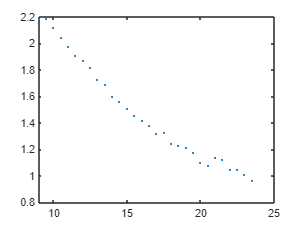

position = [9:0.5:23.5];

filtered_voltages = ans;

plot(position, filtered_voltages,'.')

filter(a)

Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position


ans =     2.1896    2.1896    2.1163    2.0430    1.9746    1.9086    1.8671    1.8182    1.7253    1.6911    1.5982    1.5640    1.5103    1.4565    1.4174    1.3783    1.3196    1.3245    1.2463    1.2268    1.2121    1.1730    1.0997    1.0802    1.1388    1.1193    1.0459    1.0459    1.0068    0.9677


save("FilteredVoltages","filtered_voltages","position");

function filtered_voltages = filter(a)
    voltages = [];
    filter_voltages = [];
    for n = 1:30
        for v = 1:30
            voltages(v) = readVoltage(a,'A3');
        end 
        filtered_voltages(n) = median(voltages);
        voltages = [];
        disp("Move to new position");
        pause(10);
    end 
end 
